clc; clear;

## Impulse response for h(n)

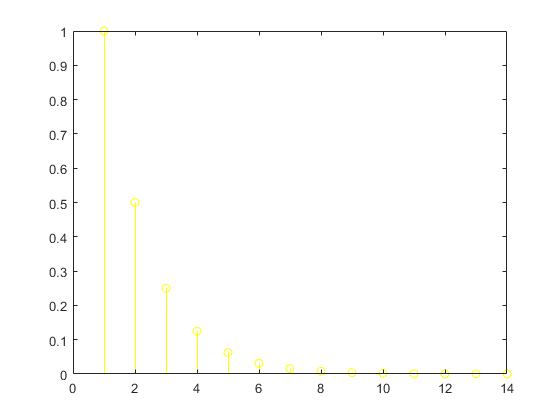

num = [1];
den = [1 -0.5];

y = impz(num,den);
stem(y,'Y');

## Convolution between x(n) and h(n)

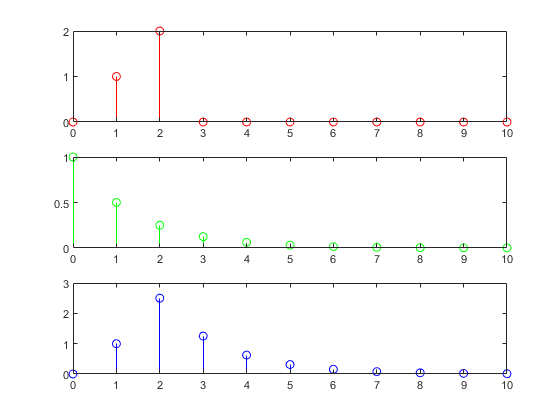

n = 0:10;
x = [0, 1, 2, 0, 0, 0, 0, 0, 0, 0, 0];
h = 0.5.^n;
y = conv(x,h);

subplot(311), stem (n,x(1:length(n)),'R'); %for x
subplot(312), stem (n,h(1:length(n)),'G'); %for h
subplot(313), stem (n,y(1:length(n)),'B'); %for y